# CAPÍTULO 05 - FLEXIÓN TRANSVERSAL

Define una viga recta para obtener reacciones, cortante, momento, pendiente y flecha. Las cargas y apoyos pueden estar entre los límites de los tramos originales.

Dimensión: viga plana con flexión en un plano. Si hay cargas fuera de ese plano, dos momentos de flexión o torsión, introduce la estructura en el capítulo 7.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

puntuales: [posición fuerzaVertical par], con fuerza positiva arriba y par antihorario positivo. distribuidas: [inicio final qInicial qFinal], positiva arriba. apoyos: [posición flecha giro]; NaN deja libre esa componente. c es la distancia desde el centroide hasta la fibra más alejada; para rectángulo es h/2.

x=[0 2 4]; E=210e9;
F=.08*.16; I=.08*.16^3/12; c=.08;
puntuales=[2 -10000 0];
distribuidas=[0 4 -2000 -2000];
apoyos=[0 0 NaN; 4 0 NaN];

## 2. Relaciones de flexión


$$\frac{dM}{dx}=V,\qquad \frac{dV}{dx}=q,\qquad M=EI\frac{d^2v}{dx^2},\qquad \theta=\frac{dv}{dx}$$


La fuerza repartida positiva apunta hacia arriba. Con esta convención, un momento positivo produce tracción en la fibra inferior y compresión en la superior. El cortante puede saltar con una fuerza puntual y el momento puede saltar con un par.

datos=struct('x',x,'E',E,'F',F,'I',I,'puntuales',puntuales, ...
    'distribuidas',distribuidas,'apoyos',apoyos);
resultado=rm_viga(datos);
xx=[]; V=[]; M=[]; v=[]; theta=[]; sigma=[]; tau=[];
for i=1:numel(resultado.campos)
    t=resultado.campos{i}; s=linspace(0,t.L,121)';
    xx=[xx;t.origen(1)+s]; V=[V;polyval(t.V,s)]; M=[M;polyval(t.M,s)];
    v=[v;polyval(t.v,s)]; theta=[theta;polyval(t.theta,s)];
    if isscalar(c), ci=c; else, ci=c(find(x<=mean(t.origen(1)+[0 t.L]),1,'last')); end
    sigma=[sigma;abs(polyval(t.M,s))*ci/resultado.datos.I(i)];
    tau=[tau;1.5*abs(polyval(t.V,s))/resultado.datos.F(i)];
end
disp(table(resultado.x,resultado.u(:,2)*1000,resultado.u(:,3), ...
    'VariableNames',{'x_m','flecha_mm','giro_rad'}));

    x_m    flecha_mm     giro_rad 
    ___    _________    __________

     0            0     -0.0026739
     2      -3.4877     8.1849e-22
     4            0      0.0026739



disp('Reacciones [N, N, N m]:'); disp(resultado.R);

Reacciones [N, N, N m]:
   1.0e+03 *

         0    9.0000   -0.0000
         0         0         0
         0    9.0000    0.0000



disp("Tension extrema de flexion [MPa]: "+max(sigma)/1e6);

Tension extrema de flexion [MPa]: 41.0156


disp("Cortante maximo si seccion rectangular [MPa]: "+max(tau)/1e6);

Cortante maximo si seccion rectangular [MPa]: 1.0547


## 3. Epiuras apiladas


$$\sigma_x(y)=-\frac{M y}{I},\qquad \tau_{\mathrm{rect},\max}=\frac{3|V|}{2F}$$


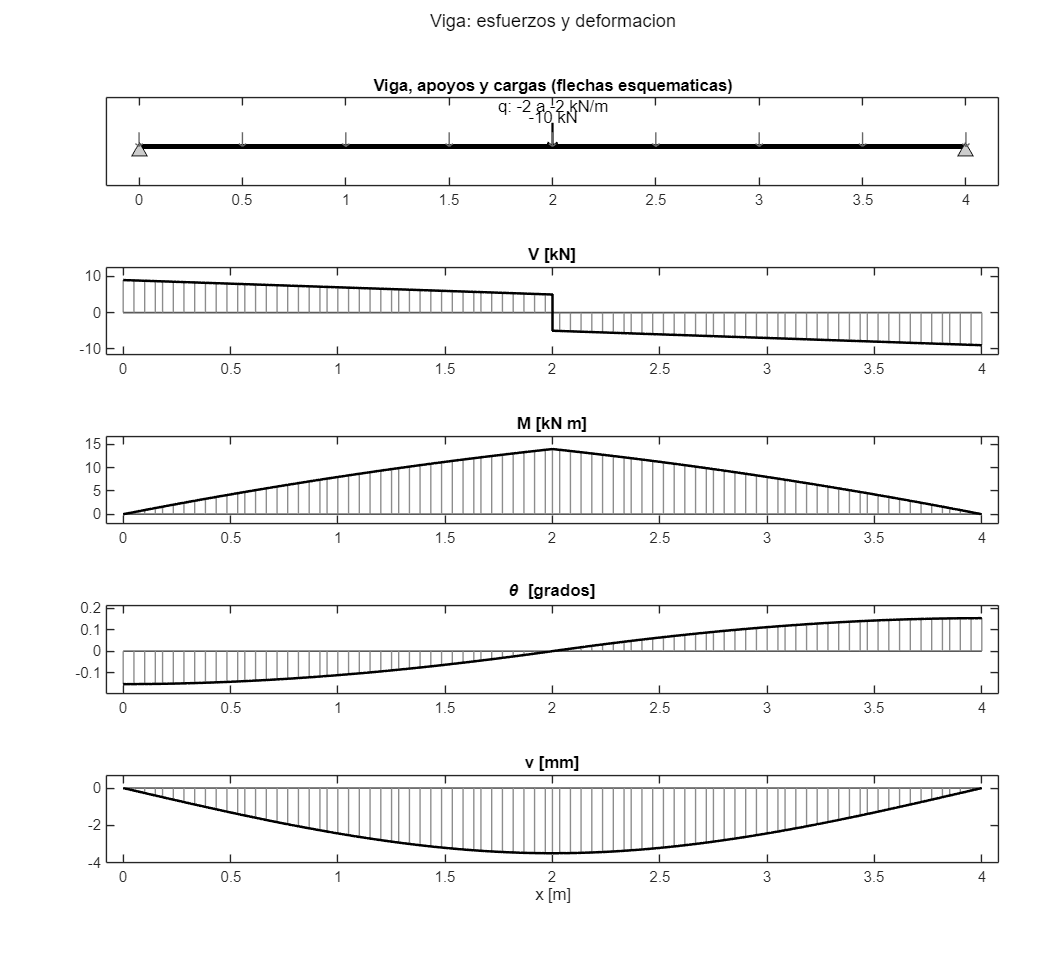

[figura,ejes]=rm_figura(5,'Viga: esfuerzos y deformacion');
rm_esquema_viga(ejes(1),datos);
rm_curva(ejes(2),xx,V/1000,'V [kN]');
rm_curva(ejes(3),xx,M/1000,'M [kN m]');
rm_curva(ejes(4),xx,theta*180/pi,'\theta [grados]');
rm_curva(ejes(5),xx,v*1000,'v [mm]'); xlabel(ejes(5),'x [m]');

## Funciones utilizadas

rm_viga: prepara y resuelve una viga. Aquí crea cortes en cargas y apoyos y obtiene los polinomios interiores.

linspace: crea puntos igualmente espaciados. Aquí prepara la representación de cada tramo.

polyval: evalúa coeficientes polinomiales. Aquí recupera V, M, giro y flecha en los puntos dibujados.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Vigas rectas Euler-Bernoulli con E, F e I constantes por tramo, cargas repartidas lineales y apoyos de desplazamiento/rotación. La tensión mostrada usa una distancia extrema c y la aproximación de cortante corresponde a sección rectangular. No calcula el centro de cortante de perfiles abiertos.

Conexión con lo anterior: Usa las inercias del capítulo 3 y extiende la compatibilidad del capítulo 1 a desplazamiento y rotación.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 05: calculo completado.');

Capitulo 05: calculo completado.
